syms u(t) v(t)

f = @(t,u,v) v;
g = @(t,u,v) -sin(u) - 0.3 * v;

a = 0;
b = 15;
n = 100;
u0 = pi/2;
v0 = 0;

[t,u,v] = MEuler_SED(f,g,a,b,n,u0,v0);

array2table([t.',u.',v.'], "VariableNames",{'t', 'u', 'v'})

ans = 101×3 table
     t          u           v    
    ____    _________    ________

       0       1.5708           0
    0.15       1.5708       -0.15
     0.3       1.5483    -0.29325
    0.45       1.5043    -0.43002
     0.6       1.4398    -0.56033
    0.75       1.3558    -0.68383
     0.9       1.2532    -0.79961
    1.05       1.1332    -0.90612
     1.2      0.99732     -1.0012
    1.35      0.84714     -1.0822
     1.5      0.68482     -1.1459
    1.65      0.51293     -1.1892
     1.8      0.33456     -1.2093
    1.95      0.15316     -1.2041
     2.1    -0.027455     -1.1728
    2.25     -0.20338     -1.1159


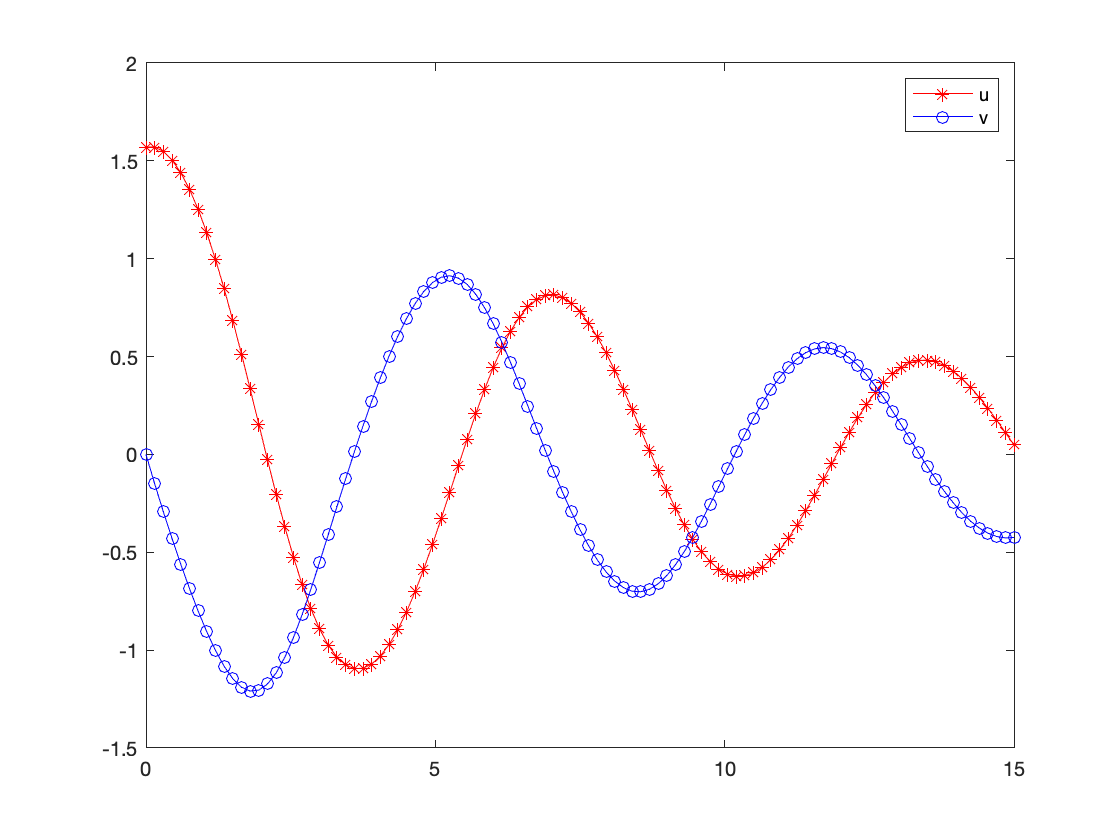


plot(t, u, "-r*");
hold on;
plot(t, v, "-bo");
hold off;
legend("u","v")